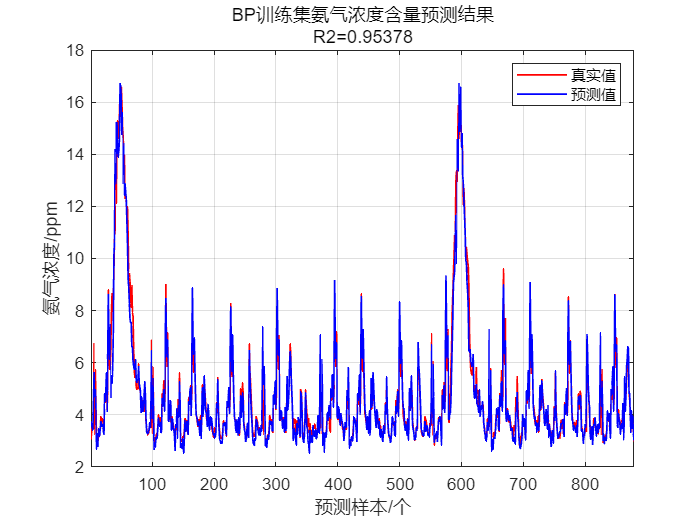

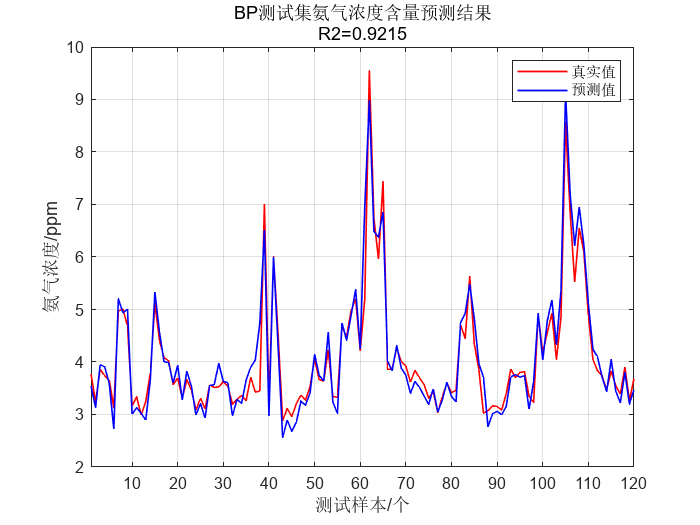

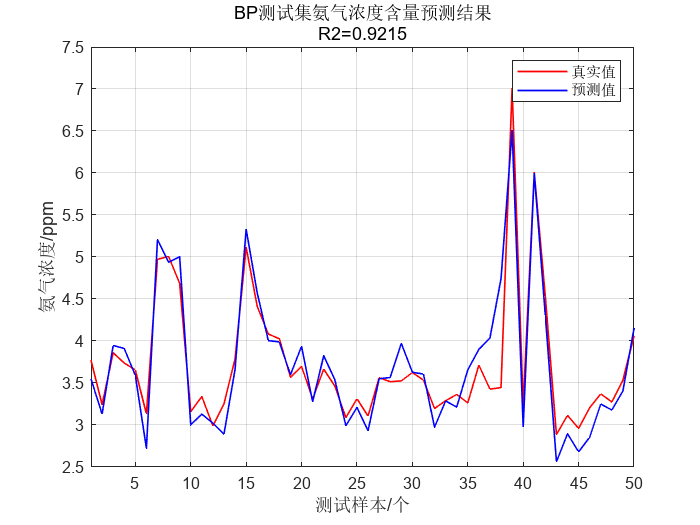

**************************


**************************


训练集数据的R2为：0.95378


测试集数据的R2为：0.9215


训练集数据的MAE为：0.28386


测试集数据的MAE为：0.21514


训练集数据的MSE为：0.26965


测试集数据的MSE为：0.10033


训练集数据的RMSE为：0.51928


测试集数据的RMSE为：0.31675


函数或变量 'tp' 无法识别。


warning off             
close all               
clear                   
clc                     


%数据导入与划分

data=readmatrix("data.xls");
t=1:999;
P_test=data(t(880:999),1:5);P_train=data(t(1:879),1:5);
T_test=data(t(880:999),6);T_train=data(t(1:879),6);


M = size(P_train, 1);N = size(P_test, 1);
temppti=P_train(:,end);temppte=P_test(:,end);
temptri=T_train;temptte=T_test;
P_train(:,5)=temptri;P_test(:,5)=temptte;
T_train=temppti;T_test=temppte;
P_train=P_train';P_test=P_test';T_train=T_train';T_test=T_test';

[p_train, ps_input] = mapminmax(P_train, 0, 1);
p_test = mapminmax('apply', P_test, ps_input);

[t_train, ps_output] = mapminmax(T_train, 0, 1);
t_test = mapminmax('apply', T_test, ps_output);

%bp模型参数设定
net = newff(p_train, t_train, 25);


net.trainParam.epochs = 1000;     
net.trainParam.goal = 1e-6;       
net.trainParam.lr = 0.01;         
net.trainFcn = 'trainbfg';

%训练
net = train(net, p_train, t_train);

%预测与反归一化
t_sim1 = sim(net, p_train);
t_sim2 = sim(net, p_test );


T_sim1 = mapminmax('reverse', t_sim1, ps_output);
T_sim2 = mapminmax('reverse', t_sim2, ps_output);

%各指标计算与绘图
for i = 1

    
    error1(i, :) = sqrt(sum((T_sim1(i, :) - T_train(i, :)).^2) ./ M);%#ok
    error2(i, :) = sqrt(sum((T_sim2(i, :) - T_test (i, :)).^2) ./ N);%#ok

    R1(i, :) = 1 - norm(T_train(i, :) - T_sim1(i, :))^2 / norm(T_train(i, :) - mean(T_train(i, :)))^2;
    R2(i, :) = 1 - norm(T_test (i, :) - T_sim2(i, :))^2 / norm(T_test (i, :) - mean(T_test (i, :)))^2;
    figure
   
    plot(1: M, T_train(i, :), 'r-', 1: M, T_sim1(i, :), 'b-', 'LineWidth', 1)
    legend('真实值', '预测值')
    xlabel('预测样本/个')
    ylabel('氨气浓度/ppm')
    %R2(i, :) = 1 - norm(T_train(i, :) - T_sim1(i, :))^2 / norm(T_train(i, :) - mean(T_train(i, :)))^2;%#ok
    string = {'BP训练集氨气浓度含量预测结果';['R2=', num2str(R1)]};
    title(string)
    xlim([1, M])
    grid
    
    figure

    plot(1: N, T_test(i, :), 'r-', 1: N, T_sim2(i, :), 'b-', 'LineWidth', 1)
    legend('真实值', '预测值')
    xlabel('测试样本/个')
    ylabel('氨气浓度/ppm')
    %R1(i, :) = 1 - norm(T_test (i, :) - T_sim2(i, :))^2 / norm(T_test (i, :) - mean(T_test (i, :)))^2;%#ok
    string = {'BP测试集氨气浓度含量预测结果';['R2=', num2str(R2)]};
    title(string)
    xlim([1, N])
    grid
    

    figure

    plot(1: N, T_test(i, :), 'r-', 1: N, T_sim2(i, :), 'b-', 'LineWidth', 1)
    legend('真实值', '预测值')
    xlabel('测试样本/个')
    ylabel('氨气浓度/ppm')
    %R1(i, :) = 1 - norm(T_test (i, :) - T_sim2(i, :))^2 / norm(T_test (i, :) - mean(T_test (i, :)))^2;%#ok
    string = {'BP测试集氨气浓度含量预测结果';['R2=', num2str(R2)]};
    title(string)
    xlim([1, 50])
    grid
    
    
    disp('**************************')
    disp('**************************')
    

    R1(i, :) = 1 - norm(T_train(i, :) - T_sim1(i, :))^2 / norm(T_train(i, :) - mean(T_train(i, :)))^2;%#ok
    R2(i, :) = 1 - norm(T_test (i, :) - T_sim2(i, :))^2 / norm(T_test (i, :) - mean(T_test (i, :)))^2;%#ok
    
    disp(['训练集数据的R2为：', num2str(R1(i, :))])
    disp(['测试集数据的R2为：', num2str(R2(i, :))])
    
    
    mae1(i, :) = sum(abs(T_sim1(i, :) - T_train(i, :))) ./ M ;%#ok
    mae2(i, :) = sum(abs(T_sim2(i, :) - T_test (i, :))) ./ N ;%#ok
    
    disp(['训练集数据的MAE为：', num2str(mae1(i, :))])
    disp(['测试集数据的MAE为：', num2str(mae2(i, :))])
    
    
    mse1 = mean((T_train(i, :)-T_sim1(i, :)).^2);
    mse2 = mean((T_test (i, :)-T_sim2(i, :)).^2);
    
    disp(['训练集数据的MSE为：', num2str(mse1)])
    disp(['测试集数据的MSE为：', num2str(mse2)])


    rmse1=sqrt(mse1);
    rmse2=sqrt(mse2);
    disp(['训练集数据的RMSE为：', num2str(rmse1(i, :))])
    disp(['测试集数据的RMSE为：', num2str(rmse2(i, :))])

    figure
    tp=T_sim2(i, :) - T_test (i, :);
%     for i=1:120
%     if tp(i)>=0.4 || tp(i)<=-0.4
%         tp(i)=(rand() - 0.5) * 0.4;
%     end
%     end
    plot(tp(1:50))
    title('BP预测误差')
    xlabel('测试集')
    ylabel('误差')

end